# Solve Celestial Mechanics Problem with High-Order Solvers

This example shows how to use `ode78` and `ode89` to solve a celestial mechanics problem that requires high accuracy in each step from the ODE solver for a successful integration. Both `ode45` and `ode113` are unable to solve the problem using the default error tolerances. Even with more stringent error thresholds, `ode89` performs best on the problem due to the high accuracy of the Runge-Kutta formulas it uses in each step.

## Problem Description

The *Pleiades problem* is a celestial mechanics problem describing the gravitational interactions of seven stars [1]. This cluster of stars is also referred to as *The Seven Sisters*, and it is visible to the human eye in the night sky due to its proximity to Earth [2]. The system of equations describing the motion of the stars in the cluster consists of 14 nonstiff second-order differential equations, which produce a system of 28 equations when rewritten in first-order form.

Newton's second law of motion relates the force applied to a body to its rate of change in momentum over time,

$F_i =\frac{\mathrm{d}}{\mathrm{d}t}p_i$.

The momentum ($p_i =m_i v_i$) has separate *x*- and *y*-components. At the same time, the universal law of gravitation describes the force working on body *i* from body *j* as

$F_{\textrm{ij}} =g\frac{m_i m_j }{{\left\|p_i -p_j \right\|}^2 }d_{\textrm{ij}}$.

The term $d_{\textrm{ij}} =\frac{p_j -p_i }{\left\|p_j -p_i \right\|}$ gives the direction of the distance between the bodies, and the masses of the bodies are $m_i =i$ for $i=1,2,\ldotp \ldotp \ldotp ,7$. For a system with many bodies, the force applied to any individual body is the sum of its interactions with all others, so


$$F_i =\sum_{i\not= j} F_{\textrm{ij}} \ldotp$$


Setting the gravitational constant $g$ equal to 1 and solving yields a system of second-order equations describing the evolution of the *x*- and *y*-components over time.


$${{x_i }^{\prime } }^{\prime } =f_i \left(x,y\right)=\sum_{j\not= i} \frac{m_j \left(x_j -x_i \right)}{r_{\textrm{ij}}^{\;3/2} },$$



$${{y_i }^{\prime } }^{\prime } =h_i \left(x,y\right)=\sum_{j\not= i} \frac{m_j \left(y_j -y_i \right)}{r_{\textrm{ij}}^{\;3/2} },$$


where $r_{\textrm{ij}} =\sqrt{{\left(x_i -x_j \right)}^2 +{\left(y_i -y_j \right)}^2 }$. Because these two equations apply for each of the seven stars in the system, 14 second-order differential equations ($\left.i=1,2,\ldotp \ldotp \ldotp ,7\right)$ describe the entire system. 

The initial conditions for the system, as given in [1], are:


$$\begin{cases}
x_0 &= (3,3,-1,-3,2,-2,2)\\
y_0 &= (3,-3,2,0,0,-4,4)\\
x_0^\prime &= (0,0,0,0,0,1.75,-1.5)\\
y_0^\prime &= (0,0,0,-1.25,1,0,0)
\end{cases}$$


To solve this system of ODEs in MATLAB®, you must code the equations into a function before calling the solvers `ode78` and `ode89`. You can either include the required functions as local functions at the end of a file (as done here), or save them as separate, named files in a directory on the MATLAB path.

## Code Equations

The ODE solvers in MATLAB require equations to be written in first-order form, $q^{\prime } =u\left(t,q\right)$. For this problem, the system of equations can be rewritten in first-order form using the substitutions $w=x^{\prime }$ and $z=y^{\prime }$. With these substitutions, the system contains 28 first-order equations organized into four groups of seven equations:

$\left[ \begin{array}{c} x_i^\prime \\ y_i^\prime \\ w_i^\prime \\ z_i^\prime \end{array}
\right] = \left[ \begin{array}{c} w_i \\ z_i \\ f_i(x,y) \\ h_i(x,y) \end{array} \right]$.

The solution vector produced by solving the system has the form


$$q=\left\lbrack \begin{array}{c}
x_i \\
y_i \\
w_i \\
z_i 
\end{array}\right\rbrack \ldotp$$


Therefore, writing the original equations in terms of the solution vector $q$ yields


$$\left\lbrack \begin{array}{c}
{x_i }^{\prime } \\
{y_i }^{\prime } \\
{w_i }^{\prime } \\
{z_i }^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\left(q_{15} ,q_{16} ,\ldotp \ldotp \ldotp ,q_{21} \right)\\
\left(q_{22} ,q_{23} ,\ldotp \ldotp \ldotp ,q_{28} \right)\\
f_i \left(x,y\right)\\
h_i \left(x,y\right)
\end{array}\right\rbrack ,$$


where $x=\left(q_1 ,q_2 ,\ldotp \ldotp \ldotp ,q_7 \right)$ and $y=\left(q_8 ,q_9 ,\ldotp \ldotp \ldotp ,q_{14} \right)$. With the equations written in the first-order form $q^{\prime } =u\left(t,q\right)$, you can now write a function that calculates the components during each time step of the solution process. A function that codes this system of equations is:

In this function, the $x$ and $y$ values are extracted directly from the solution vector $q$, as are the first 14 components of the output. Then, the function uses the position values to calculate the distances between all seven stars, and these distances are used in the code for $f_i \left(x,y\right)$ and $h_i \left(x,y\right)$. 

## Set Optional Parameters

Use the `odeset` function to set the value of several optional parameters:

- Specify stringent error tolerances of `1e-13` and `1e-15` for the relative and absolute error tolerances, respectively. 

- Turn on the display of solver statistics.

opts = odeset("RelTol",1e-13,"AbsTol",1e-15,"Stats","on");

## Solve System of Equations

Create a column vector with the initial conditions and a time vector with regularly spaced points in the range $\left\lbrack 0,15\right\rbrack$. When you specify a time vector with more than two elements, the solver returns solutions at the time points you specify.

init = [3 3 -1 -3 2 -2 2 ...
        3 -3 2 0 0 -4 4 ...
        0 0 0 0 0 1.75 -1.5 ...
        0 0 0 -1.25 1 0 0]';
tspan = linspace(1,15,200);

Now, solve the equations using both `ode78` and `ode89` by specifying the equations, time span, initial values, and options. Use `tic` and `toc` to time each solver for comparison (note that timings can differ depending on your computer).

tic
[t78,q78] = ode78(@pleiades,tspan,init,opts);
toc
tic
[t89,q89] = ode89(@pleiades,tspan,init,opts);
toc

The output indicates that `ode89` is best suited for solving the problem, because it is faster and has fewer failed steps.

## Plot Solution Curves

The first 14 components of `q89` contain the *x* and *y* positions for each of the seven stars, as obtained by `ode89`. Plot these solution components to see the trajectories of all the stars over time.

plot(q89(:,1),q89(:,8),'--',...
     q89(:,2),q89(:,9),'--',...
     q89(:,3),q89(:,10),'--',...
     q89(:,4),q89(:,11),'--',...
     q89(:,5),q89(:,12),'--',...
     q89(:,6),q89(:,13),'--',...
     q89(:,7),q89(:,14),'--')
title('Position of Pleiades Stars, Solved by ODE89')
xlabel('X Position')
ylabel('Y Position')

## Create Animation of Results

Because the trajectories of the stars overlap considerably, a better way to visualize the results is to create an animation showing the stars move over time. The function `AnimateOrbits`, included as a local function at the end of this example, accepts the output from a solver for this problem and creates an animated GIF file in the current folder that shows the stars move along their trajectories.

For example, you can generate an animation with the output from the `ode89` solver using the command

The following is a sample output GIF.

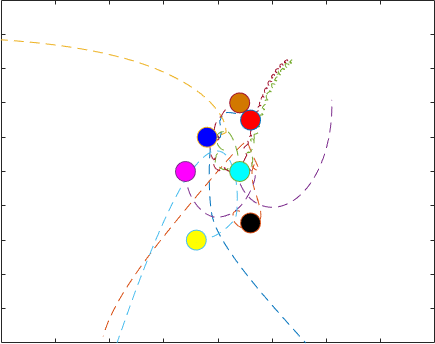

## References

[1] Hairer, E., et al. *Solving Ordinary Differential Equations I: Nonstiff Problems*. 2nd rev. ed, Springer, 2009.

[2] “Pleiades.” *Wikipedia*, 21 June 2021. *Wikipedia*, [https://en.wikipedia.org/wiki/Pleiades](https://en.wikipedia.org/wiki/Pleiades).

## Local Functions

This section includes the local functions called by the ODE solver to calculate the solution. Alternatively, you can save these functions as their own files in a directory on the MATLAB path.

function dqdt = pleiades(t,q)
  x = q(1:7);
  y = q(8:14);
  xDist = (x - x.');
  yDist = (y - y.');
  r = (xDist.^2+yDist.^2).^(3/2);
  m = (1:7)';
  dqdt = [q(15:28);
          sum(xDist.*m./r,1,'omitnan').';
          sum(yDist.*m./r,1,'omitnan').'];
end
%-----------------------------------------------------------------
function AnimateOrbits(t,q)
for k = 1:length(t)
    plot(q(:,1),q(:,8),'--',q(:,2),q(:,9),'--',...
         q(:,3),q(:,10),'--',q(:,4),q(:,11),'--',...
         q(:,5),q(:,12),'--',q(:,6),q(:,13),'--',...
         q(:,7),q(:,14),'--')
    hold on
    xlim([-20 20])
    ylim([-10 10])
    sz = 15;
    plot(q(k,1),q(k,8),'o','MarkerSize',sz,'MarkerFaceColor','r')
    plot(q(k,2),q(k,9),'o','MarkerSize',sz,'MarkerFaceColor','k')
    plot(q(k,3),q(k,10),'o','MarkerSize',sz,'MarkerFaceColor','b')
    plot(q(k,4),q(k,11),'o','MarkerSize',sz,'MarkerFaceColor','m')
    plot(q(k,5),q(k,12),'o','MarkerSize',sz,'MarkerFaceColor','c')
    plot(q(k,6),q(k,13),'o','MarkerSize',sz,'MarkerFaceColor','y')
    plot(q(k,7),q(k,14),'o','MarkerSize',sz,'MarkerFaceColor',[210 120 0]./255)
    hold off
    drawnow
    M(k) = getframe(gca);
    im{k} = frame2im(M(k));
end

filename = "orbits.gif";
for idx = 1:length(im)
    [A,map] = rgb2ind(im{idx},256);
    if idx == 1
        imwrite(A,map,filename,'gif','LoopCount',Inf,'DelayTime',0);
    else
        imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',0);
    end
end
close all
end

*Copyright 2021 The MathWorks, Inc.*